# Question 2

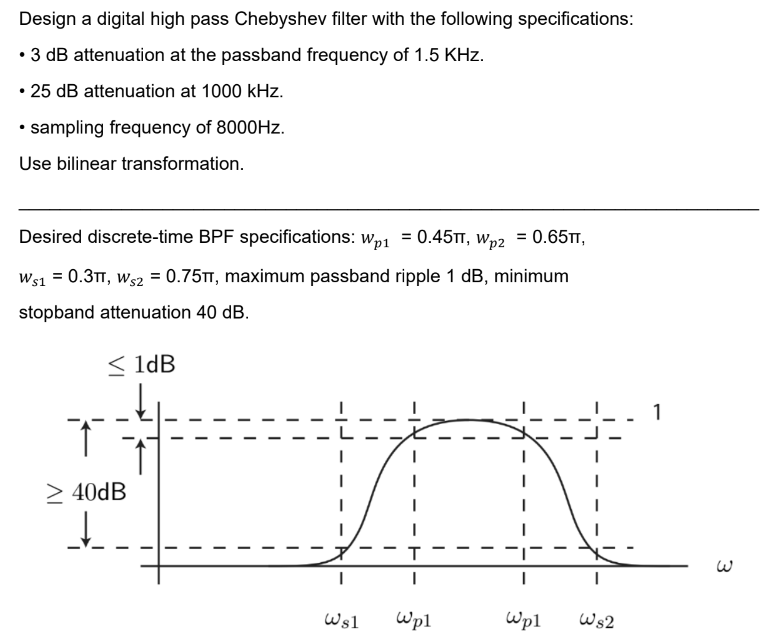

as ws1 = 0.3π  => , fs1 = 0.3*8000/2 = 1200Hz

as wp1 = 0.45π  => , fs1 = 0.45*8000/2 = 1800Hz

as wp2 = 0.65π  => , fs1 = 0.65*8000/2 = 2600Hz

as ws2 = 0.75π  => , fs1 = 0.75*8000/2 = 3000Hz

## Band Pass Filter 

### system specs given in Discrete time frequency response

wp1 = 0.45*pi;
wp2 = 0.65*pi;
ws1 = 0.3*pi;
ws2 = 0.75*pi;
fs = 8000;
ds = 10^(-40/20)

ds = 0.0100

dp = 10^(-1/20)

dp = 0.8913

### Prewarping here W = Ω (analog frequency)

Wp1 = tan(wp1/2);
Wp2 = tan(wp2/2);
Ws1 = tan(ws1/2);
Ws2 = tan(ws2/2);

### Making Wp1*Wp2 = Ws1*Ws2

if(Wp1*Wp2 ~= Ws1*Ws2)
    if(Wp1*Wp2 > Ws1*Ws2) %increase Ws1
        Ws1 =  Wp1*Wp2/Ws2;
        disp('Ws1 is changed')
    else                    % decrease Ws2
        Ws2 =  Wp1*Wp2/Ws1;
        disp('Ws2 is changed')
    end
else
    disp('Wp1*Wp2 = Ws1*Ws2, no need to change')
end

Wp1*Wp2 = Ws1*Ws2, no need to change


### Wsnlp (Ωsnlp) , Wp (Ωp) -> specs to design NLPF

Wo = (Wp1*Wp2)^0.5;
Wp = 1;
Wsnlp = (Ws2-Ws1)/(Wp2-Wp1);
Q = Wo/(Wp2-Wp1);

### Nb and Wc (Ωc) -> parameters to find NLPF analog equation

Nb = ceil(0.5*log(((1/ds)^2-1)/((1/dp)^2-1))/log(Wsnlp/Wp))

Nb = 7

Wc = Wp/(((1/dp)^2-1))^(1/(2*Nb))

Wc = 1.1013

### Equation of Analog LPF

syms snlp
syms k
bk = sin(pi*(2*k+1)/(2*Nb));

b0 = subs(bk,k,0);
b1 = subs(bk,k,1);
b2 = subs(bk,k,2);

Hnlp = Wc^4/((snlp+Wc)*(snlp^2 + 2*b0*Wc*snlp+Wc^2)*(snlp^2 + 2*b1*Wc*snlp+Wc^2)*(snlp^2 + 2*b2*Wc*snlp+Wc^2))

$$Hnlp = \frac{3312791912518195}{2251799813685248\,\left(\mathrm{snlp}+\frac{4959933675565753}{4503599627370496}\right)\,\left({\mathrm{snlp}}^{2}+\frac{4959933675565753\,\sin\left(\frac{\pi }{14}\right)\,\mathrm{snlp}}{2251799813685248}+\frac{42675831733055}{35184372088832}\right)\,\left({\mathrm{snlp}}^{2}+\frac{4959933675565753\,\sin\left(\frac{3\,\pi }{14}\right)\,\mathrm{snlp}}{2251799813685248}+\frac{42675831733055}{35184372088832}\right)\,\left({\mathrm{snlp}}^{2}+\frac{4959933675565753\,\sin\left(\frac{5\,\pi }{14}\right)\,\mathrm{snlp}}{2251799813685248}+\frac{42675831733055}{35184372088832}\right)}$$

### Analog Equation of BPF

syms s
Hbpf = subs(Hnlp, snlp, Q*(s^2+Wo^2)/(Wo*s))

$$Hbpf = \begin{array}{l} \frac{3312791912518195}{2251799813685248\,\left(\frac{4503599627370496\,\sigma_{2}}{5316790736581865\,s}+\frac{4959933675565753}{4503599627370496}\right)\,\left(\sigma_{1}+\frac{9919867351131506\,\sin\left(\frac{\pi }{14}\right)\,\sigma_{2}}{5316790736581865\,s}+\frac{42675831733055}{35184372088832}\right)\,\left(\sigma_{1}+\frac{9919867351131506\,\sin\left(\frac{3\,\pi }{14}\right)\,\sigma_{2}}{5316790736581865\,s}+\frac{42675831733055}{35184372088832}\right)\,\left(\sigma_{1}+\frac{9919867351131506\,\sin\left(\frac{5\,\pi }{14}\right)\,\sigma_{2}}{5316790736581865\,s}+\frac{42675831733055}{35184372088832}\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{20282409603651670423947251286016\,{\sigma_{2}}^{2}}{28268263736602730579543846878225\,s^{2}}\\ \sigma_{2}=\frac{854491669977061\,s^{2}}{562949953421312}+\frac{5363486518837149046993319454123}{2535301200456458802993406410752} \end{array}$$

### Bilinear Transformation

syms z
Hz = subs(Hbpf,s,(1-z^-1)/(1+z^-1))

$$Hz = \begin{array}{l} -\frac{3312791912518195}{2251799813685248\,\left(\frac{4503599627370496\,\left(\frac{1}{z}+1\right)\,\sigma_{3}}{\sigma_{1}}-\frac{4959933675565753}{4503599627370496}\right)\,\left(\sigma_{2}-\frac{9919867351131506\,\sin\left(\frac{\pi }{14}\right)\,\left(\frac{1}{z}+1\right)\,\sigma_{3}}{\sigma_{1}}+\frac{42675831733055}{35184372088832}\right)\,\left(\sigma_{2}-\frac{9919867351131506\,\sin\left(\frac{3\,\pi }{14}\right)\,\left(\frac{1}{z}+1\right)\,\sigma_{3}}{\sigma_{1}}+\frac{42675831733055}{35184372088832}\right)\,\left(\sigma_{2}-\frac{9919867351131506\,\sin\left(\frac{5\,\pi }{14}\right)\,\left(\frac{1}{z}+1\right)\,\sigma_{3}}{\sigma_{1}}+\frac{42675831733055}{35184372088832}\right)}\\ \mathrm{where}\\ \sigma_{1}=5316790736581865\,\left(\frac{1}{z}-1\right)\\ \sigma_{2}=\frac{20282409603651670423947251286016\,\sigma_{5}\,{\sigma_{3}}^{2}}{28268263736602730579543846878225\,\sigma_{4}}\\ \sigma_{3}=\frac{854491669977061\,\sigma_{4}}{562949953421312\,\sigma_{5}}+\frac{5363486518837149046993319454123}{2535301200456458802993406410752}\\ \sigma_{4}={\left(\frac{1}{z}-1\right)}^{2}\\ \sigma_{5}={\left(\frac{1}{z}+1\right)}^{2} \end{array}$$

### Frequency Response

syms w
Hw = subs(Hz,z,exp(1j*w))

$$Hw = \begin{array}{l} -\frac{3312791912518195}{2251799813685248\,\left(\frac{4503599627370496\,\sigma_{3}\,\sigma_{4}}{\sigma_{1}}-\frac{4959933675565753}{4503599627370496}\right)\,\left(\sigma_{2}-\frac{9919867351131506\,\sin\left(\frac{\pi }{14}\right)\,\sigma_{3}\,\sigma_{4}}{\sigma_{1}}+\frac{42675831733055}{35184372088832}\right)\,\left(\sigma_{2}-\frac{9919867351131506\,\sin\left(\frac{3\,\pi }{14}\right)\,\sigma_{3}\,\sigma_{4}}{\sigma_{1}}+\frac{42675831733055}{35184372088832}\right)\,\left(\sigma_{2}-\frac{9919867351131506\,\sin\left(\frac{5\,\pi }{14}\right)\,\sigma_{3}\,\sigma_{4}}{\sigma_{1}}+\frac{42675831733055}{35184372088832}\right)}\\ \mathrm{where}\\ \sigma_{1}=5316790736581865\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)\\ \sigma_{2}=\frac{20282409603651670423947251286016\,{\sigma_{3}}^{2}\,{\sigma_{4}}^{2}}{28268263736602730579543846878225\,{\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}^{2}}\\ \sigma_{3}=\frac{854491669977061\,{\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}^{2}}{562949953421312\,{\sigma_{4}}^{2}}+\frac{5363486518837149046993319454123}{2535301200456458802993406410752}\\ \sigma_{4}={\mathrm{e}}^{-w\,\mathrm{i}}+1 \end{array}$$

## Plot of desired frequency response of BPF filter

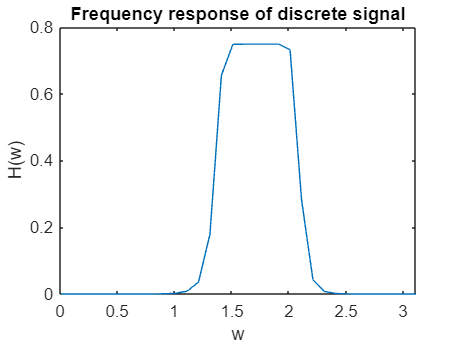

w_subs = 0.01:0.1:pi;
Hw_subs = double(subs(Hw,w,w_subs));
plot(w_subs,abs(Hw_subs))
title('Frequency response of discrete signal')
ylabel('H(w)')
xlabel('w')

### Making sine signals

We are making sine in discrete time, Hence

lets take a sine wave of frequency less than ws1(0.3pi) = 0.2*pi. and

another sine wave of frequency between than wp1,wp2 (0.45pi,0.65pi) = 0.5*pi

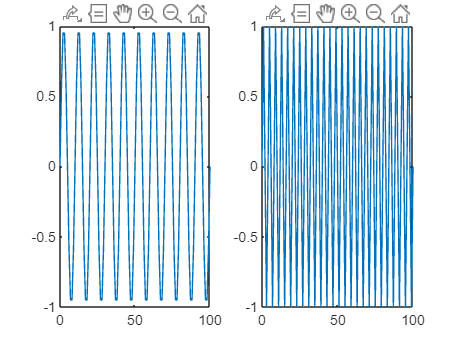

n = 0:100;
stop_sine= sin(0.2*pi*n);
pass_sine = sin(0.5*pi*n);

subplot(1,2,1)
plot(n,stop_sine)
subplot(1,2,2)
plot(n,pass_sine)

### Converting to frequency response

stop_sine_w = fft(stop_sine,100)

stop_sine_w =   -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 -50.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i


pass_sine_w = fft(pass_sine,100)

pass_sine_w =   -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 -50.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


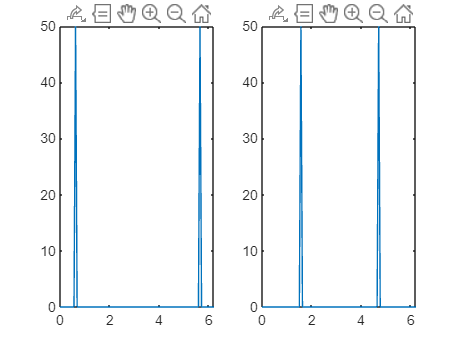

k = 0.01:99+0.01;
wplot = 2*pi*k/100;

subplot(1,2,1)
plot(wplot,abs(stop_sine_w))
subplot(1,2,2)
plot(wplot,abs(pass_sine_w))

### Passing through the filter

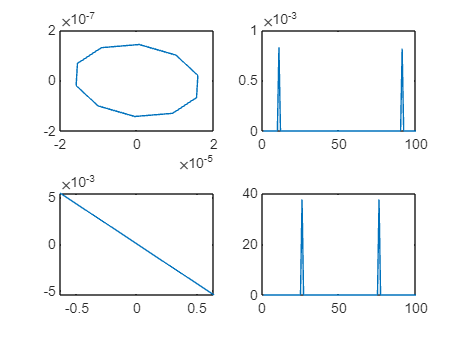

filter = subs(Hw,w,wplot);
stop_output = double(filter.* stop_sine_w);
pass_output = double(filter.* pass_sine_w);

stop_n = ifft(stop_output,100);
pass_n = ifft(pass_output,100);

clf
subplot(2,2,1)
plot(stop_n)

subplot(2,2,2)
plot(abs(stop_output))

subplot(2,2,3)
plot(pass_n)

subplot(2,2,4)
plot(abs(pass_output))